% Name of the file
folder = '../dpm/';

selectedFile = "C:\Users\williamstoy\Documents\GitHub\inertial-microfluidics-optimization\microfluidics-optimization_files\user_files\data\dpm\dpm_data_cw120_ch60_cl500_nh30_nl60_q217_re40_step19.dpm";
d = dir(selectedFile);
name = d.name;
s = split(d(1).name, '_');
s{end} = [s{end}(1:4), '*', s{end}(end-3:end)];
f = join(s, '_');
filename = f{1};

strings = split(filename, '_');
ch_found = 0;
cw_found = 0;
for k = 1:length(strings)
    if startsWith(strings{k},'cw')
        cw = str2double(strings{k}(3:end));
        cw_found = 1;
    end

    if startsWith(strings{k},'ch')
        ch = str2double(strings{k}(3:end));
        ch_found = 1;
    end
end

if ~ch_found || ~cw_found
    error('Poorly formed filename string (does not contain cw and ch');
end

d = dir([folder, filename]);
numberOfSteps = length(d);
for i = 1:numberOfSteps
    [stepNumberOutlet, outletDataTable] = processDataFromStepFile([d(i).folder, '\', d(i).name]);
    [stepNumberInlet, inletDataTable] = processDataFromStepFile([d(i).folder, '\dpm_inlet', d(i).name(4:end)]);

    outletData{stepNumberOutlet} = outletDataTable;
    inletData{stepNumberInlet} = inletDataTable;
end

Step Number: 1


Step Number: 1


Step Number: 10


Step Number: 10


Step Number: 100


Step Number: 100


Step Number: 11


Step Number: 11


Step Number: 12


Step Number: 12


Step Number: 13


Step Number: 13


Step Number: 14


Step Number: 14


Step Number: 15


Step Number: 15


Step Number: 16


Step Number: 16


Step Number: 17


Step Number: 17


Step Number: 18


Step Number: 18


Step Number: 19


Step Number: 19


Step Number: 2


Step Number: 2


Step Number: 20


Step Number: 20


Step Number: 21


Step Number: 21


Step Number: 22


Step Number: 22


Step Number: 23


Step Number: 23


Step Number: 24


Step Number: 24


Step Number: 25


Step Number: 25


Step Number: 26


Step Number: 26


Step Number: 27


Step Number: 27


Step Number: 28


Step Number: 28


Step Number: 29


Step Number: 29


Step Number: 3


Step Number: 3


Step Number: 30


Step Number: 30


Step Number: 31


Step Number: 31


Step Number: 32


Step Number: 32


Step Number: 33


Step Number: 33


Step Number: 34


Step Number: 34


Step Number: 35


Step Number: 35


Step Number: 36


Step Number: 36


Step Number: 37


Step Number: 37


Step Number: 38


Step Number: 38


Step Number: 39


Step Number: 39


Step Number: 4


Step Number: 4


Step Number: 40


Step Number: 40


Step Number: 41


Step Number: 41


Step Number: 42


Step Number: 42


Step Number: 43


Step Number: 43


Step Number: 44


Step Number: 44


Step Number: 45


Step Number: 45


Step Number: 46


Step Number: 46


Step Number: 47


Step Number: 47


Step Number: 48


Step Number: 48


Step Number: 49


Step Number: 49


Step Number: 5


Step Number: 5


Step Number: 50


Step Number: 50


Step Number: 51


Step Number: 51


Step Number: 52


Step Number: 52


Step Number: 53


Step Number: 53


Step Number: 54


Step Number: 54


Step Number: 55


Step Number: 55


Step Number: 56


Step Number: 56


Step Number: 57


Step Number: 57


Step Number: 58


Step Number: 58


Step Number: 59


Step Number: 59


Step Number: 6


Step Number: 6


Step Number: 60


Step Number: 60


Step Number: 61


Step Number: 61


Step Number: 62


Step Number: 62


Step Number: 63


Step Number: 63


Step Number: 64


Step Number: 64


Step Number: 65


Step Number: 65


Step Number: 66


Step Number: 66


Step Number: 67


Step Number: 67


Step Number: 68


Step Number: 68


Step Number: 69


Step Number: 69


Step Number: 7


Step Number: 7


Step Number: 70


Step Number: 70


Step Number: 71


Step Number: 71


Step Number: 72


Step Number: 72


Step Number: 73


Step Number: 73


Step Number: 74


Step Number: 74


Step Number: 75


Step Number: 75


Step Number: 76


Step Number: 76


Step Number: 77


Step Number: 77


Step Number: 78


Step Number: 78


Step Number: 79


Step Number: 79


Step Number: 8


Step Number: 8


Step Number: 80


Step Number: 80


Step Number: 81


Step Number: 81


Step Number: 82


Step Number: 82


Step Number: 83


Step Number: 83


Step Number: 84


Step Number: 84


Step Number: 85


Step Number: 85


Step Number: 86


Step Number: 86


Step Number: 87


Step Number: 87


Step Number: 88


Step Number: 88


Step Number: 89


Step Number: 89


Step Number: 9


Step Number: 9


Step Number: 90


Step Number: 90


Step Number: 91


Step Number: 91


Step Number: 92


Step Number: 92


Step Number: 93


Step Number: 93


Step Number: 94


Step Number: 94


Step Number: 95


Step Number: 95


Step Number: 96


Step Number: 96


Step Number: 97


Step Number: 97


Step Number: 98


Step Number: 98


Step Number: 99


Step Number: 99


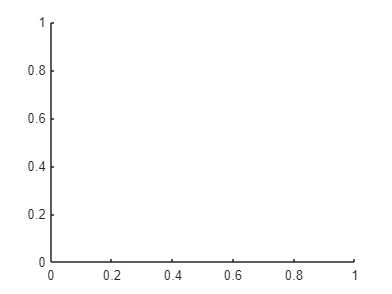


close all; clc; figure; ax = axes;

## display

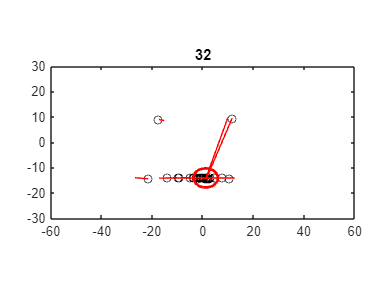

displayStep =32;
% Display the table
plot(outletData{displayStep}.z * 1e6, outletData{displayStep}.y * 1e6, 'ko');
hold on;
for i = 1:length(inletData{displayStep}.z)
    plot([inletData{displayStep}.z(i), outletData{displayStep}.z(i)] * 1e6, ...
         [inletData{displayStep}.y(i), outletData{displayStep}.y(i)] * 1e6, ...
        'r');
end

hold off;

% draw an ellipse of the standard deviation bounds
% Ellipse parameters
center_x = mean(outletData{displayStep}.z) * 1e6;
center_y = mean(outletData{displayStep}.y) * 1e6;
width = 2 * 3 * std(outletData{displayStep}.z) * 1e6;  % Semi-major axis (horizontal axis length)
height = 2 * 3 * std(outletData{displayStep}.y) * 1e6;   % Semi-minor axis (vertical axis length)

% Draw the ellipse using the rectangle function
rectangle('Position', [center_x - width/2, center_y - height/2, width, height], ...
          'Curvature', [1, 1], ...
          'EdgeColor', 'r', ...
          'LineWidth', 2);

axis equal;
xlim([-cw/2, cw/2]);
ylim([-ch/2, ch/2]);
title(displayStep);

## functions

function [stepNumber, dataTable] = processDataFromStepFile(fname)
% Open the file
    d = dir(fname);
    folder = d(1).folder;
    filename = d(1).name;

    fid = fopen([folder, '\', filename], 'r');

    % get the step name from the file
    % Use regular expression to match the pattern and extract the step number
    pattern = 'step(\d+)\.dpm';
    tokens = regexp(filename, pattern, 'tokens');
    
    % Convert the extracted number (stored in tokens{1}{1}) to double
    if ~isempty(tokens)
        stepNumber = str2double(tokens{1}{1});
        disp(['Step Number: ', num2str(stepNumber)]);
    else
        error('Pattern not found in filename.');
    end
    
    % Read the file line by line and store the data
    data = [];
    while ~feof(fid)
        line = fgetl(fid);
        
        % Check if line starts with '((' indicating data
        if startsWith(line, '((')
            
            % Split the line based on spaces
            value_texts = strsplit(line(4:end-1), ' ');
            value_texts{12} = value_texts{12}(1:end-1); % remove the trailing ')'
            
            id_data = strsplit(value_texts{end}, ':');
            value_texts{end} = id_data{2}(1:end-1);

            values = str2double(value_texts);
            
            % Append to data
            data = [data; values];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Convert the array data to a table
    columnNames = {'x', 'y', 'z', 'u', 'v', 'w', 'diameter', 't', 'mass-flow', 'mass', 'frequency', 'time', 'name'};
    dataTable = array2table(data, 'VariableNames', columnNames);
end